%% build_SummaryTable.m
% Scan a folder of per-cell Excel files, extract metadata from filenames,
% read 1–3 rows based on condition keys, map values by header name,
% and write a single SummaryTable.xlsx to the same folder.

% ---------- User input ----------
inputFolder = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/Output_240424to0525/summaryTbl_240424to0525';
% --------------------------------

% Output schema (exact order)
outVars = { ...
    'CellID','treatment','wpi','condition_filename','date','cellNumber', ...
    'Expter_Name', ...                                %%% <<< CHANGED (added column)
    'Expt_cond', ...
    'I_0_3','I_1','I_3','I_10','I_30','I_100','I_300','I_1000', ...
    'avgRundown_per_iteration','threshold','Rmax','linear_interpolation_Slope' ...
};

outTypes = [ ...
    repmat({'string'},1,8), ...                      %%% <<< CHANGED (was 7 text cols; now 8 incl. Expter_Name)
    repmat({'double'},1,12) ...
];

% Prepare empty summary table with fixed schema
SummaryTable = table('Size',[0 numel(outVars)], ...
    'VariableTypes',outTypes,'VariableNames',outVars);

% Gather files (.xlsx and .xls)
files = [dir(fullfile(inputFolder,'*.xlsx')); dir(fullfile(inputFolder,'*.xls'))];
files = files(~[files.isdir]);  % safety

if isempty(files)
    fprintf('No .xlsx or .xls files found in: %s\n', inputFolder);
end

for k = 1:numel(files)
    fpath = fullfile(files(k).folder, files(k).name);
    [~, base, ~] = fileparts(fpath);

    % ---- Parse filename (split by underscores only) ----
    % Expected patterns (condition may include underscores/hyphens):
    % 1) treatment _ wpi _ condition _ date _ cellToken
    % 2) treatment _ wpi _ condition _ date _ cellToken _ Expter
    try
        meta = parseFilenameTokens(base); % no regexp for tokenization
    catch ME
        warning('Skipping file (bad filename format): %s\n  -> %s', files(k).name, ME.message);
        continue;
    end

    % Determine search keys (ordered aCSF -> GBZ -> NBQX_APV)
    keys = computeKeys(meta.condition_filename);

    fprintf('Processing: %s\n', files(k).name);

    % Try to read the first sheet
    T = [];
    try
        T = readtable(fpath, 'FileType','spreadsheet');
    catch ME
        warning('  Could not read file: %s\n  -> %s', files(k).name, ME.message);
        continue;
    end

    % Normalize header names for mapping (case/space-insensitive)
    varNames = string(T.Properties.VariableNames);
    normMap = buildHeaderIndex(varNames);  % containers.Map of normalizedName -> colIndex

    % Column A (first column) will be used for matching search keys
    colA = string(strtrim(T{:,1}));
    colA_lower = lower(colA);

    % For each key, append matches (all rows) or a single NaN row if none
    for qi = 1:numel(keys)
        key = keys(qi);
        mask = strcmp(colA_lower, lower(strtrim(key)));
        idx = find(mask);

        if isempty(idx)
            fprintf('  Key %-9s : NO match -> append NaNs\n', key);
            SummaryTable = [SummaryTable; buildOutRow(meta, key, T, [], normMap)]; %#ok<AGROW>
        else
            fprintf('  Key %-9s : %d match(es)\n', key, numel(idx));
            for ii = 1:numel(idx)
                SummaryTable = [SummaryTable; buildOutRow(meta, key, T, idx(ii), normMap)]; %#ok<AGROW>
            end
        end
    end
end

Processing: MMZ_2w_aCSF-GBZ_240525_cell5_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)


Processing: MMZ_2w_aCSF_240517_cell5_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: MMZ_2w_aCSF_240525_cell7_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: PBS_2w_aCSF-GBZ_240504_cell5_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)


Processing: PBS_2w_aCSF-GBZ_240515_cell6_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)


Processing: PBS_2w_aCSF-GBZ_240522_cell2_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)


Processing: PBS_2w_aCSF-GBZ_240525_cell5_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)


Processing: PBS_2w_aCSF_240424_cell4_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: PBS_2w_aCSF_240424_cell7_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: PBS_2w_aCSF_240425_cell4_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: PBS_2w_aCSF_240425_cell6_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: PBS_2w_aCSF_240504_cell3_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: PBS_2w_aCSF_240511_cell1_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: PBS_2w_aCSF_240515_cell3_HM.xlsx


  Key aCSF      : 1 match(es)


Processing: PBS_2w_aCSF_240525_cell2_HM.xlsx


  Key aCSF      : 1 match(es)



% Write output
outFile = fullfile(inputFolder, 'SummaryTable_240424to0525.xlsx');
writetable(SummaryTable, outFile);
fprintf('Done. Wrote %d rows to %s\n', height(SummaryTable), outFile);

Done. Wrote 20 rows to /Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/Output_240424to0525/summaryTbl_240424to0525/SummaryTable_240424to0525.xlsx




%% ----------------- Helper functions -----------------

function meta = parseFilenameTokens(base)
% Parse tokens from basename (no path/extension).
% Tokenization policy: split on '_' only.
% Supports two endings:
%   ... _ date _ cellN
%   ... _ date _ cellN _ Expter
    parts = split(string(base), '_');
    if numel(parts) < 5
        error('Expected at least 5 underscore-separated tokens.');
    end

    treatment = parts(1);
    wpi       = parts(2);

    %%% <<< CHANGED: allow optional trailing experimenter token
    % Detect whether the last token is a cell token or an experimenter.
    lastTok = parts(end);
    if startsWith(lower(lastTok), "cell") || ~isempty(regexp(lastTok, '^cell\d+$', 'once'))
        % No experimenter in filename
        expter    = "";                          % none
        cellToken = parts(end);
        dateStr   = parts(end-1);
        if numel(parts) == 5
            condition = parts(3);
        else
            condition = strjoin(parts(3:end-2), '_');
        end
    else
        % Has experimenter (e.g., ... _ cell2 _ HM)
        expter    = lastTok;
        cellToken = parts(end-1);
        dateStr   = parts(end-2);
        if numel(parts) == 6
            condition = parts(3);
        else
            condition = strjoin(parts(3:end-3), '_');
        end
    end
    %%% <<< end CHANGED

    % Extract numeric cell number from cellToken (e.g., "cell7" -> 7). If missing -> NaN.
    tok = regexp(cellToken, '\d+', 'match', 'once');  % allowed here (not for tokenization)
    if isempty(tok), cellNum = NaN; else, cellNum = str2double(tok); end

    % Preserve originals as strings (except numeric cellNumber)
    meta = struct();
    meta.CellID             = string(base);
    meta.treatment          = treatment;
    meta.wpi                = wpi;
    meta.condition_filename = condition;
    meta.date               = dateStr;
    meta.cellNumber         = cellNum;
    meta.Expter_Name        = string(expter);         %%% <<< CHANGED (store experimenter)
end

function keys = computeKeys(condition_filename)
% Build ordered list of keys based on condition in filename.
    c = lower(condition_filename);
    keys = string({'aCSF'});  % always
    if contains(c, 'gbz')
        keys(end+1) = "GBZ";
    end
    if contains(c, 'nbqx_apv')
        keys(end+1) = "NBQX_APV";
    end
end

function norm = normName(s)
% Normalize header names for robust matching (case- and space-insensitive).
    norm = lower(regexprep(strtrim(string(s)), '[^\w]|[ ]', ''));
end

function normMap = buildHeaderIndex(varNames)
% Build lookup of normalized variable names -> column index
    normMap = containers.Map('KeyType','char','ValueType','double');
    for i = 1:numel(varNames)
        key = char(normName(varNames(i)));
        if ~isKey(normMap, key)
            normMap(key) = i;
        end
    end
end

function rowT = buildOutRow(meta, key, T, rowIdx, normMap)
% Construct a one-row table in the required schema, pulling values by header name.
    outVars = { ...
        'CellID','treatment','wpi','condition_filename','date','cellNumber', ...
        'Expter_Name', ...                            %%% <<< CHANGED (added column)
        'Expt_cond', ...
        'I_0_3','I_1','I_3','I_10','I_30','I_100','I_300','I_1000', ...
        'avgRundown_per_iteration','threshold','Rmax','linear_interpolation_Slope' ...
    };
    outTypes = [ ...
        repmat({'string'},1,8), ...                  %%% <<< CHANGED (text count updated)
        repmat({'double'},1,12) ...
    ];

    % Initialize with empties/NaNs
    rowT = table('Size',[1 numel(outVars)], ...
        'VariableTypes',outTypes,'VariableNames',outVars);

    % Fill metadata/text fields
    rowT.CellID             = meta.CellID;
    rowT.treatment          = meta.treatment;
    rowT.wpi                = meta.wpi;
    rowT.condition_filename = meta.condition_filename;
    rowT.date               = meta.date;
    rowT.cellNumber         = meta.cellNumber;
    rowT.Expter_Name        = meta.Expter_Name;      %%% <<< CHANGED (populate new column)
    rowT.Expt_cond          = string(key);

    % If no matching data row, leave numeric as NaN
    if isempty(rowIdx)
        return;
    end

    % Map source headers -> target names (one-to-one by name)
    targetNames = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000", ...
                   "avgRundown_per_iteration","threshold","Rmax","linear_interpolation_Slope"];

    for t = 1:numel(targetNames)
        tgt = targetNames(t);
        srcKey = char(normName(tgt));
        if isKey(normMap, srcKey)
            col = normMap(srcKey);
            val = T{rowIdx, col};
            rowT.(tgt) = coerceDouble(val);
        else
            rowT.(tgt) = NaN;
        end
    end
end

function x = coerceDouble(val)
% Coerce a scalar/1x1 cell/char/string to double; non-numeric -> NaN.
    if iscell(val), val = val{1}; end
    if isnumeric(val) && isscalar(val)
        x = double(val); return;
    end
    if isstring(val) || ischar(val)
        tmp = str2double(strtrim(string(val)));
        x = tmp; if isnan(tmp), x = NaN; end
        return;
    end
    try
        x = double(val);
        if ~isscalar(x), x = NaN; end
    catch
        x = NaN;
    end
end


## Figure plotting

### Compare by treatment

#### Lorcan

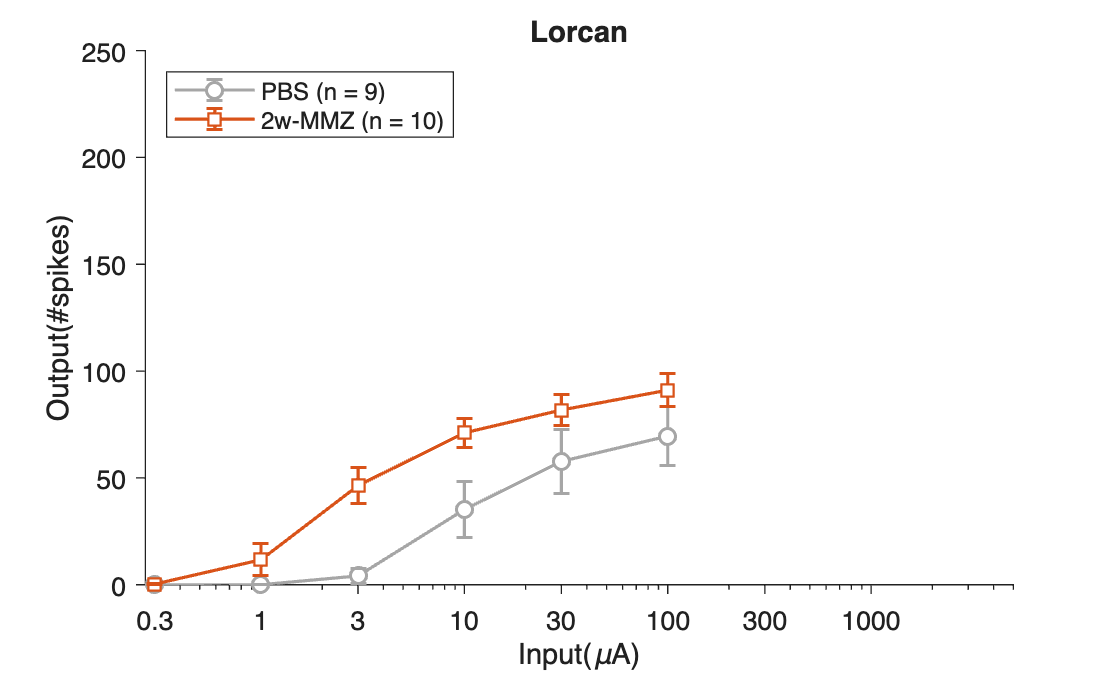

% ===== Output directory =====
PBS_MMZ_2w_aCSF_Expter_FigureOutputDir = ...
"/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/FigureOutputDirectory/PBS_MMZ_2w_aCSF_Lorcan_FigureOutputDir";
if ~exist(PBS_MMZ_2w_aCSF_Expter_FigureOutputDir,'dir')
    mkdir(PBS_MMZ_2w_aCSF_Expter_FigureOutputDir);
end

fname = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/summaryTbl/SummaryTable_PBS_MMZ_2w_aCSF_Lorcan_all.xlsx';
T = readtable(fname, 'FileType','spreadsheet');

% --- Set up filters for grouping comparisons ----
needCols = {'Expter_Name','wpi','Expt_cond'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

mask = strcmpi(T.Expter_Name,"Lorcan") & strcmpi(T.wpi,"2w") & strcmpi(T.Expt_cond,"aCSF");
T_HM_2w_aCSF = T(mask,:);

% Color palette
col.black = [0 0 0];
col.gray  = 0.65*[1 1 1];
col.blue  = [0 0.4470 0.7410];
col.red   = [0.85 0.325 0.098];

% --- (1) check repeated CellID ---
ids = string(T_HM_2w_aCSF.CellID);
[u, ~, ic] = unique(ids,'stable');
counts = accumarray(ic,1);
dups = u(counts>1);
if ~isempty(dups)
    error('repeated cell: %s', strjoin(cellstr(dups), ', '));
end

% --- (2) Cell count per treatment ---
T2 = T_HM_2w_aCSF;
T2.treatment = string(T2.treatment);
CellCountTbl = groupcounts(T2,'treatment');
CellCountTbl.Properties.VariableNames = {'treatment','CellCount','Percentage'};

% --- (3) column means / SD / SEM per treatment ---
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","linear_interpolation_Slope"];
varsParams_PlotTitle = ["Threshold","O_m_a_x","Slope"];
varsAll = [varsSpikes varsParams];

for v = varsAll
    x = T2.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end
    T2.(v) = reshape(x,[],1);
end

treats = unique(T2.treatment,'stable');
stats = struct();
for i = 1:numel(treats)
    tr = treats(i);
    rows = (T2.treatment==tr);

    Xspk = T2{rows, varsSpikes};
    mSpk = mean(Xspk, 1, 'omitnan');
    sdSpk = std(Xspk, 0, 1, 'omitnan');
    nSpk  = sum(~isnan(Xspk), 1);
    semSpk = sdSpk ./ max(nSpk,1).^0.5;

    Xpar = T2{rows, varsParams};
    mPar = mean(Xpar, 1, 'omitnan');
    sdPar = std(Xpar, 0, 1, 'omitnan');
    nPar  = sum(~isnan(Xpar), 1);
    semPar = sdPar ./ max(nPar,1).^0.5;

    stats.(tr).meanSpikes = mSpk;
    stats.(tr).sdSpikes   = sdSpk;
    stats.(tr).semSpikes  = semSpk;
    stats.(tr).nSpikes    = nSpk;
    stats.(tr).meanPars   = mPar;
    stats.(tr).sdPars     = sdPar;
    stats.(tr).semPars    = semPar;
    stats.(tr).nPars      = nPar;
end

% --- (4) IO curve: mean ± SEM across intensities ---
xVals = [0.3 1 3 10 30 100 300 1000];   % µA

figIO = figure('Color','w'); hold on;
if isfield(stats,'PBS')
    errorbar(xVals, stats.PBS.meanSpikes, stats.PBS.semSpikes, ...
        'o-','Color',col.gray,'MarkerFaceColor','w','LineWidth',1.2,'CapSize',6);
end
if isfield(stats,'MMZ')
    errorbar(xVals, stats.MMZ.meanSpikes, stats.MMZ.semSpikes, ...
        's-','Color',col.red,'MarkerFaceColor','w','LineWidth',1.2,'CapSize',6);
end
set(gca,'XScale','log','Box','off','TickDir','out');
ylim([0 250]);
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input(\muA)'); ylabel('Output(#spikes)');
legend({'PBS (n = 9)','2w-MMZ (n = 10)'},'Location','northwest'); title('Lorcan');

% --- SAVE IO FIGURE ---
exportgraphics(figIO, fullfile(PBS_MMZ_2w_aCSF_Expter_FigureOutputDir, 'IOcurve_meanSEM.png'), 'Resolution',300);

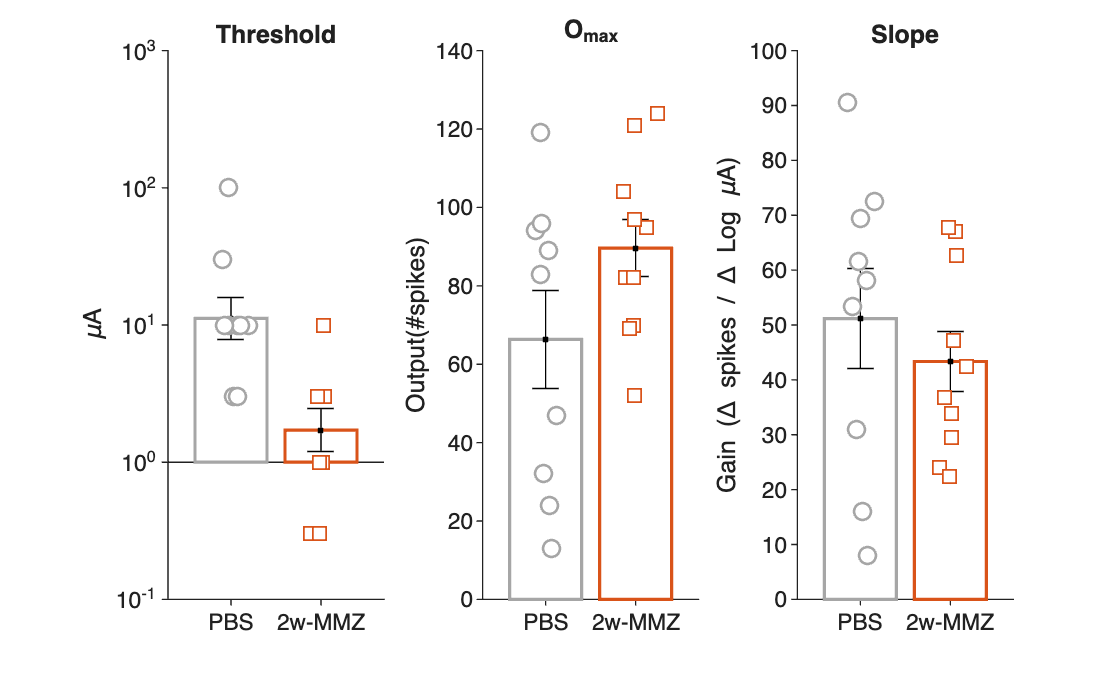


% --- (5) bar charts for threshold / Rmax / slope ---
figBars = figure('Color','w');
xJitter = 0.08; ptSize = 40;

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    PBS_raw = T2{T2.treatment=="PBS", varsParams(p)};
    MMZ_raw = T2{T2.treatment=="MMZ", varsParams(p)};

    if varsParams(p) == "threshold"
        PBS_dp = log10(PBS_raw);
        MMZ_dp = log10(MMZ_raw);

        PBS_mean = mean(PBS_dp,'omitnan');
        MMZ_mean = mean(MMZ_dp,'omitnan');
        PBS_sem  = std(PBS_dp,0,'omitnan')/sqrt(sum(~isnan(PBS_dp)));
        MMZ_sem  = std(MMZ_dp,0,'omitnan')/sqrt(sum(~isnan(MMZ_dp)));

        bar(1, PBS_mean, 'FaceColor','none','EdgeColor',col.gray,'LineWidth',1.2);
        bar(2, MMZ_mean, 'FaceColor','none','EdgeColor',col.red,'LineWidth',1.2);
        errorbar([1 2], [PBS_mean MMZ_mean], [PBS_sem MMZ_sem],'k.', 'CapSize',10);

        x1 = 1 + xJitter*randn(numel(PBS_dp),1);
        scatter(x1, PBS_dp, ptSize, 'o', 'MarkerEdgeColor',col.gray,'MarkerFaceColor','w','LineWidth',1);
        x2 = 2 + xJitter*randn(numel(MMZ_dp),1);
        scatter(x2, MMZ_dp, ptSize, 's', 'MarkerEdgeColor',col.red,'MarkerFaceColor','w','LineWidth',1);

         % ---- Fixed y-axis: 10^-1 to 10^3 ----
        ylim([-1 3]);                 % log10 range
        yticks(-1:3);                 % ticks at -1,0,1,2,3
        yticklabels( arrayfun(@(k) sprintf('10^{%d}',k), -1:3, 'UniformOutput', false) );
        ylabel('\muA');

        title(varsParams_PlotTitle{p});
        xlim([0.3 2.7]); xticks([1 2]); xticklabels({'PBS','2w-MMZ'});
        set(gca,'TickDir','out');

    else
        PBS_dp = PBS_raw;  MMZ_dp = MMZ_raw;

        PBS_mean = stats.PBS.meanPars(p);
        PBS_sem  = stats.PBS.semPars(p);
        MMZ_mean = stats.MMZ.meanPars(p);
        MMZ_sem  = stats.MMZ.semPars(p);

        bar(1, PBS_mean, 'FaceColor','none','EdgeColor',col.gray,'LineWidth',1.2);
        bar(2, MMZ_mean, 'FaceColor','none','EdgeColor',col.red,'LineWidth',1.2);
        errorbar([1 2], [PBS_mean MMZ_mean], [PBS_sem MMZ_sem], 'k.', 'CapSize',10);

        x1 = 1 + xJitter*randn(numel(PBS_dp),1);
        scatter(x1, PBS_dp, ptSize, 'o', 'MarkerEdgeColor',col.gray,'MarkerFaceColor','w','LineWidth',1);
        x2 = 2 + xJitter*randn(numel(MMZ_dp),1);
        scatter(x2, MMZ_dp, ptSize, 's', 'MarkerEdgeColor',col.red,'MarkerFaceColor','w','LineWidth',1);

        
        xlim([0.3 2.7]); xticks([1 2]); xticklabels({'PBS','2w-MMZ'});
        title(varsParams_PlotTitle{p});
        set(gca,'TickDir','out');

        if varsParams(p) == "Rmax"
            ylabel('Output(#spikes)');
        elseif varsParams(p) == "linear_interpolation_Slope"
            ylabel('Gain (\Delta spikes / \Delta Log \muA)');
        end
    end
end

% --- SAVE BAR FIGURE ---
exportgraphics(figBars, fullfile(PBS_MMZ_2w_aCSF_Expter_FigureOutputDir, 'ParamsBars_threshold_Rmax_Slope.png'), 'Resolution',300);




% === Outputs you can inspect ===
CellCountTbl      % table of treatment vs CellCount

CellCountTbl = 2×3 table
    treatment    CellCount    Percentage
    _________    _________    __________

      "MMZ"         10          52.632  
      "PBS"          9          47.368  


stats         % struct with mean/SD/SEM for spikes & parameters

stats = struct with fields:
    MMZ: [1×1 struct]
    PBS: [1×1 struct]


#### HM

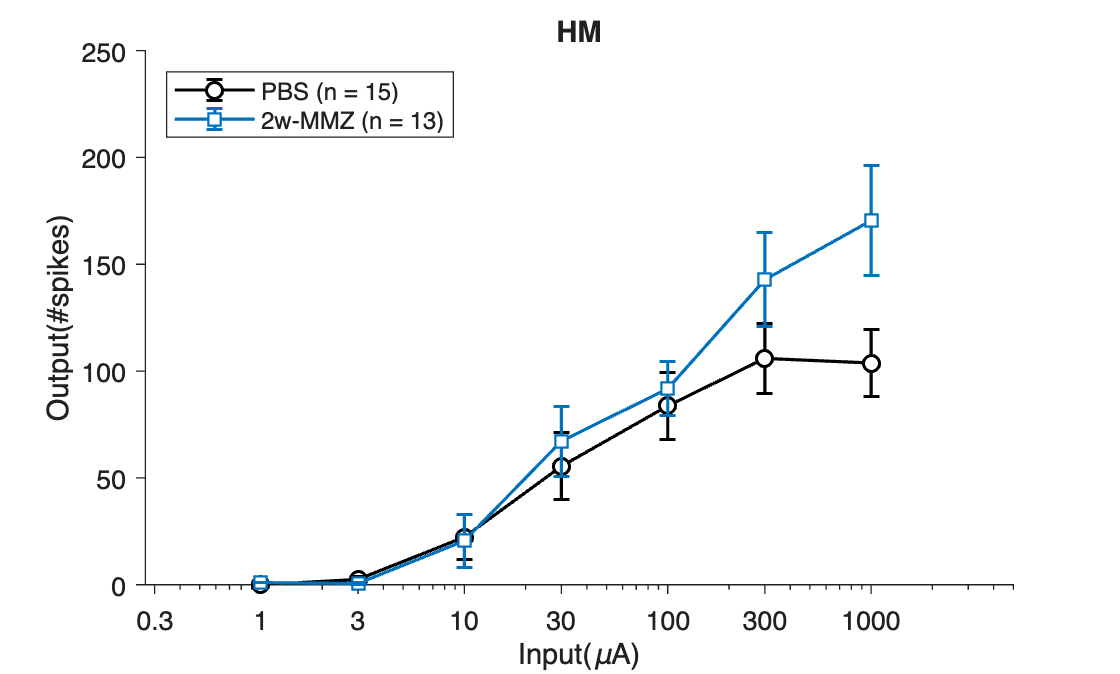

% ===== Output directory =====
PBS_MMZ_2w_aCSF_Expter_FigureOutputDir = ...
"/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/FigureOutputDirectory/PBS_MMZ_2w_aCSF_HM_FigureOutputDir";
if ~exist(PBS_MMZ_2w_aCSF_Expter_FigureOutputDir,'dir')
    mkdir(PBS_MMZ_2w_aCSF_Expter_FigureOutputDir);
end

fname = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/summaryTbl/SummaryTable_PBS_MMZ_2w_aCSF-GBZ_HM_all.xlsx';
T = readtable(fname, 'FileType','spreadsheet');

% --- Set up filters for grouping comparisons ----
needCols = {'Expter_Name','wpi','Expt_cond'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

% --- Make sure avgRundown_per_iteration exists and convert to double ---
colName = 'avgRundown_per_iteration';
assert(ismember(colName, T.Properties.VariableNames), ...
    'Missing column: %s', colName);

tmp = T.(colName);
if isnumeric(tmp)
    tmpd = double(tmp);
elseif iscell(tmp)
    tmpd = cellfun(@(y) str2double(string(y)), tmp);
else
    tmpd = str2double(string(tmp));
end
T.(colName) = tmpd;  % Now numeric; missing/empty -> NaN

% --- Filter:
% HM (Expter_Name), 2w (wpi), aCSF (Expt_cond),
% AND keep only rows where avgRundown_per_iteration has data (non-NaN, finite)
mask = strcmpi(T.Expter_Name,"HM") & ...
       strcmpi(T.wpi,"2w") & ...
       strcmpi(T.Expt_cond,"aCSF") & ...
       isfinite(T.(colName));   % <-- this line enforces "has data"

T_HM_2w_aCSF = T(mask,:);

% Color palette
col.black = [0 0 0];
col.gray  = 0.65*[1 1 1];
col.blue  = [0 0.4470 0.7410];
col.red   = [0.85 0.325 0.098];

% --- (1) check repeated CellID ---
ids = string(T_HM_2w_aCSF.CellID);
[u, ~, ic] = unique(ids,'stable');
counts = accumarray(ic,1);
dups = u(counts>1);
if ~isempty(dups)
    error('repeated cell: %s', strjoin(cellstr(dups), ', '));
end

% --- (2) Cell count per treatment ---
T2 = T_HM_2w_aCSF;
T2.treatment = string(T2.treatment);
CellCountTbl = groupcounts(T2,'treatment');
CellCountTbl.Properties.VariableNames = {'treatment','CellCount','Percentage'};

% --- (3) column means / SD / SEM per treatment ---
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","linear_interpolation_Slope"];
varsParams_PlotTitle = ["Threshold","O_m_a_x","Slope"];
varsAll = [varsSpikes varsParams];

for v = varsAll
    x = T2.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end
    T2.(v) = reshape(x,[],1);
end

treats = unique(T2.treatment,'stable');
stats = struct();
for i = 1:numel(treats)
    tr = treats(i);
    rows = (T2.treatment==tr);

    Xspk = T2{rows, varsSpikes};
    mSpk = mean(Xspk, 1, 'omitnan');
    sdSpk = std(Xspk, 0, 1, 'omitnan');
    nSpk  = sum(~isnan(Xspk), 1);
    semSpk = sdSpk ./ max(nSpk,1).^0.5;

    Xpar = T2{rows, varsParams};
    mPar = mean(Xpar, 1, 'omitnan');
    sdPar = std(Xpar, 0, 1, 'omitnan');
    nPar  = sum(~isnan(Xpar), 1);
    semPar = sdPar ./ max(nPar,1).^0.5;

    stats.(tr).meanSpikes = mSpk;
    stats.(tr).sdSpikes   = sdSpk;
    stats.(tr).semSpikes  = semSpk;
    stats.(tr).nSpikes    = nSpk;
    stats.(tr).meanPars   = mPar;
    stats.(tr).sdPars     = sdPar;
    stats.(tr).semPars    = semPar;
    stats.(tr).nPars      = nPar;
end

% --- (4) IO curve: mean ± SEM across intensities ---
xVals = [0.3 1 3 10 30 100 300 1000];   % µA

figIO = figure('Color','w'); hold on;
if isfield(stats,'PBS')
    errorbar(xVals, stats.PBS.meanSpikes, stats.PBS.semSpikes, ...
        'o-','Color',col.black,'MarkerFaceColor','w','LineWidth',1.2,'CapSize',6);
end
if isfield(stats,'MMZ')
    errorbar(xVals, stats.MMZ.meanSpikes, stats.MMZ.semSpikes, ...
        's-','Color',col.blue,'MarkerFaceColor','w','LineWidth',1.2,'CapSize',6);
end
set(gca,'XScale','log','Box','off','TickDir','out');
ylim([0 250]);
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input(\muA)'); ylabel('Output(#spikes)');
legend({'PBS (n = 15)','2w-MMZ (n = 13)'},'Location','northwest'); title('HM');

% --- SAVE IO FIGURE ---
exportgraphics(figIO, fullfile(PBS_MMZ_2w_aCSF_Expter_FigureOutputDir, 'IOcurve_meanSEM.png'), 'Resolution',300);

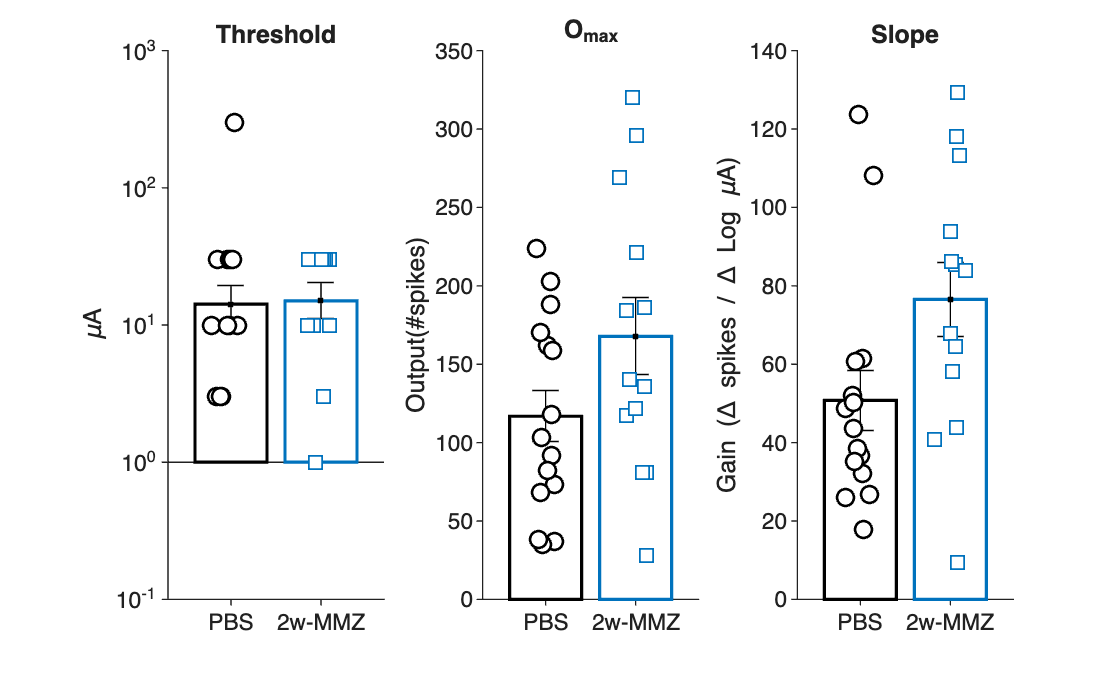


% --- (5) bar charts for threshold / Rmax / slope ---
figBars = figure('Color','w');
xJitter = 0.08; ptSize = 40;

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    PBS_raw = T2{T2.treatment=="PBS", varsParams(p)};
    MMZ_raw = T2{T2.treatment=="MMZ", varsParams(p)};

    if varsParams(p) == "threshold"
        PBS_dp = log10(PBS_raw);
        MMZ_dp = log10(MMZ_raw);

        PBS_mean = mean(PBS_dp,'omitnan');
        MMZ_mean = mean(MMZ_dp,'omitnan');
        PBS_sem  = std(PBS_dp,0,'omitnan')/sqrt(sum(~isnan(PBS_dp)));
        MMZ_sem  = std(MMZ_dp,0,'omitnan')/sqrt(sum(~isnan(MMZ_dp)));

        bar(1, PBS_mean, 'FaceColor','none','EdgeColor',col.black,'LineWidth',1.2);
        bar(2, MMZ_mean, 'FaceColor','none','EdgeColor',col.blue,'LineWidth',1.2);
        errorbar([1 2], [PBS_mean MMZ_mean], [PBS_sem MMZ_sem],'k.', 'CapSize',10);

        x1 = 1 + xJitter*randn(numel(PBS_dp),1);
        scatter(x1, PBS_dp, ptSize, 'o', 'MarkerEdgeColor',col.black,'MarkerFaceColor','w','LineWidth',1);
        x2 = 2 + xJitter*randn(numel(MMZ_dp),1);
        scatter(x2, MMZ_dp, ptSize, 's', 'MarkerEdgeColor',col.blue,'MarkerFaceColor','w','LineWidth',1);

        % Fixed y-axis for threshold (log10 space)
        ylim([-1 3]); yticks(-1:3);
        yticklabels( arrayfun(@(k) sprintf('10^{%d}',k), -1:3, 'UniformOutput', false) );
        ylabel('\muA');

        title(varsParams_PlotTitle{p});
        xlim([0.3 2.7]); xticks([1 2]); xticklabels({'PBS','2w-MMZ'});
        set(gca,'TickDir','out');

    else
        PBS_dp = PBS_raw;  MMZ_dp = MMZ_raw;

        PBS_mean = stats.PBS.meanPars(p);
        PBS_sem  = stats.PBS.semPars(p);
        MMZ_mean = stats.MMZ.meanPars(p);
        MMZ_sem  = stats.MMZ.semPars(p);

        bar(1, PBS_mean, 'FaceColor','none','EdgeColor',col.black,'LineWidth',1.2);
        bar(2, MMZ_mean, 'FaceColor','none','EdgeColor',col.blue,'LineWidth',1.2);
        errorbar([1 2], [PBS_mean MMZ_mean], [PBS_sem MMZ_sem], 'k.', 'CapSize',10);

        x1 = 1 + xJitter*randn(numel(PBS_dp),1);
        scatter(x1, PBS_dp, ptSize, 'o', 'MarkerEdgeColor',col.black,'MarkerFaceColor','w','LineWidth',1);
        x2 = 2 + xJitter*randn(numel(MMZ_dp),1);
        scatter(x2, MMZ_dp, ptSize, 's', 'MarkerEdgeColor',col.blue,'MarkerFaceColor','w','LineWidth',1);

        xlim([0.3 2.7]); xticks([1 2]); xticklabels({'PBS','2w-MMZ'});
        title(varsParams_PlotTitle{p});
        set(gca,'TickDir','out');

        if varsParams(p) == "Rmax"
            ylabel('Output(#spikes)');
        elseif varsParams(p) == "linear_interpolation_Slope"
            ylabel('Gain (\Delta spikes / \Delta Log \muA)');
        end
    end
end

% --- SAVE BAR FIGURE ---
exportgraphics(figBars, fullfile(PBS_MMZ_2w_aCSF_Expter_FigureOutputDir, 'ParamsBars_threshold_Rmax_Slope.png'), 'Resolution',300);




% === Outputs you can inspect ===
CellCountTbl      % table of treatment vs CellCount

CellCountTbl = 2×3 table
    treatment    CellCount    Percentage
    _________    _________    __________

      "MMZ"         13          46.429  
      "PBS"         15          53.571  


stats         % struct with mean/SD/SEM for spikes & parameters

stats = struct with fields:
    MMZ: [1×1 struct]
    PBS: [1×1 struct]


### Compare by experimenter & treatment

%% Compare by experimenter & treatment (HM vs Lorcan; PBS vs MMZ) at 2w, aCSF
outDir = "/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/FigureOutputDirectory/PBS_MMZ_2w_aCSF_Lorcan_HM_FigureOutputDir";
if ~exist(outDir,'dir'), mkdir(outDir); end

fname = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/summaryTbl/SummaryTable_PBS_MMZ_2w_aCSF_Lorcan_2w_aCSF-GBZ_HM_combined.xlsx';
T = readtable(fname, 'FileType','spreadsheet');

% --- columns we need
needCols = {'Expter_Name','wpi','Expt_cond','treatment','CellID','avgRundown_per_iteration'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

%% ---- FIXED FILTERS: 2w + aCSF ----
maskBase = strcmpi(T.wpi,"2w") & strcmpi(T.Expt_cond,"aCSF");

% --- (1) keep only rows with data in avgRundown_per_iteration
tmp = T.avgRundown_per_iteration;
% convert to numeric
if isnumeric(tmp)
    tmpd = double(tmp);
elseif iscell(tmp)
    tmpd = cellfun(@(y) str2double(string(y)), tmp);
else
    tmpd = str2double(string(tmp));
end
T.avgRundown_per_iteration = tmpd;     % NaN for empties/nonnumeric
maskRun = isfinite(T.avgRundown_per_iteration);   % has data (not NaN/Inf)

T = T(maskBase & maskRun, :);

% sanity: repeated CellID within this subset?
ids = string(T.CellID);
[u,~,ic] = unique(ids,'stable');
counts = accumarray(ic,1);
dups = u(counts>1);
if ~isempty(dups)
    error('repeated cell: %s', strjoin(cellstr(dups), ', '));
end

%% ---- numeric columns ----
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","linear_interpolation_Slope"];
varsAll    = [varsSpikes varsParams];

for v = varsAll
    x = T.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end
    T.(v) = reshape(x,[],1);
end

%% ---- build groups: experimenter + treatment ----
expNames  = ["HM","Lorcan"];
treatList = ["PBS","MMZ"];
T.treatment    = string(T.treatment);
T.Expter_Name  = string(T.Expter_Name);

% (5) Cell count per group (Expter_Name x treatment), show & save
[groupID, groupTbl] = findgroups(T(:, {'Expter_Name','treatment'}));   % grouping keys
counts = splitapply(@numel, T.CellID, groupID);                         % count rows per group

CellCountTbl = groupTbl;                         % start with the key columns
CellCountTbl.CellCount = counts;                 % add counts
CellCountTbl.Percentage = 100*counts/sum(counts);% add percentages

disp(CellCountTbl);

    Expter_Name    treatment    CellCount    Percentage
    ___________    _________    _________    __________

     "HM"            "MMZ"         13           27.66  
     "HM"            "PBS"         15          31.915  
     "Lorcan"        "MMZ"         10          21.277  
     "Lorcan"        "PBS"          9          19.149  



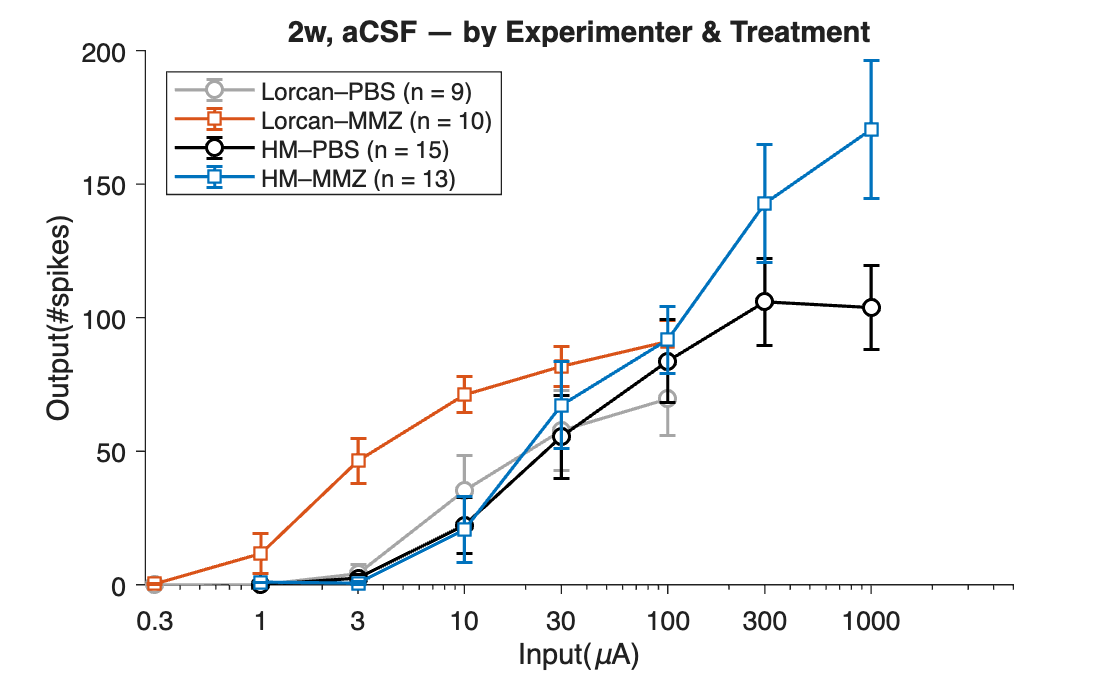

writetable(CellCountTbl, fullfile(outDir,'CellCounts_by_Experimenter_Treatment.csv'));


% Color palette
col.black = [0 0 0];
col.gray  = 0.65*[1 1 1];
col.blue  = [0 0.4470 0.7410];
col.red   = [0.85 0.325 0.098];

% mapping (experimenter x treatment) -> color & marker
styleMap = struct( ...
  'HM_PBS',     struct('C',col.black, 'M','o'), ...
  'Lorcan_PBS', struct('C',col.gray,  'M','o'), ...
  'HM_MMZ',     struct('C',col.blue,  'M','s'), ...
  'Lorcan_MMZ', struct('C',col.red,   'M','s') ...
);

% compute stats for each group
stats = struct();
for e = expNames
    for tr = treatList
        rows = (T.Expter_Name==e) & (T.treatment==tr);
        if ~any(rows), continue; end

        Xspk = T{rows, varsSpikes};
        mSpk = mean(Xspk, 1, 'omitnan');
        sdSpk = std(Xspk, 0, 1, 'omitnan');
        nSpk = sum(~isnan(Xspk), 1);
        semSpk = sdSpk ./ max(nSpk,1).^0.5;

        Xpar = T{rows, varsParams};
        mPar = mean(Xpar, 1, 'omitnan');
        sdPar = std(Xpar, 0, 1, 'omitnan');
        nPar = sum(~isnan(Xpar), 1);
        semPar = sdPar ./ max(nPar,1).^0.5;

        key = sprintf('%s_%s', e, tr);
        stats.(key).meanSpikes = mSpk;
        stats.(key).sdSpikes   = sdSpk;
        stats.(key).semSpikes  = semSpk;
        stats.(key).nSpikes    = nSpk;
        stats.(key).meanPars   = mPar;
        stats.(key).sdPars     = sdPar;
        stats.(key).semPars    = semPar;
        stats.(key).nPars      = nPar;
    end
end

%% ---- IO curves (mean ± SEM) ----
xVals = [0.3 1 3 10 30 100 300 1000];   % µA
figIO = figure('Color','w'); hold on;

plotOrder = {'Lorcan_PBS','Lorcan_MMZ','HM_PBS','HM_MMZ'};
legNames  = {'Lorcan–PBS (n = 9)','Lorcan–MMZ (n = 10)','HM–PBS (n = 15)','HM–MMZ (n = 13)'};

for i = 1:numel(plotOrder)
    k = plotOrder{i};
    if ~isfield(stats,k), continue; end
    st  = stats.(k);
    sty = styleMap.(k);
    errorbar(xVals, st.meanSpikes, st.semSpikes, ...
        [sty.M '-'], 'Color', sty.C, 'MarkerFaceColor','w', ...
        'LineWidth',1.2,'CapSize',6);
end

set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input(\muA)'); ylabel('Output(#spikes)');
legend(legNames( ismember(plotOrder, fieldnames(stats)) ), 'Location','northwest');
title('2w, aCSF — by Experimenter & Treatment');

% save IO figure
exportgraphics(figIO, fullfile(outDir,'IOcurve_meanSEM.png'), 'Resolution',300);

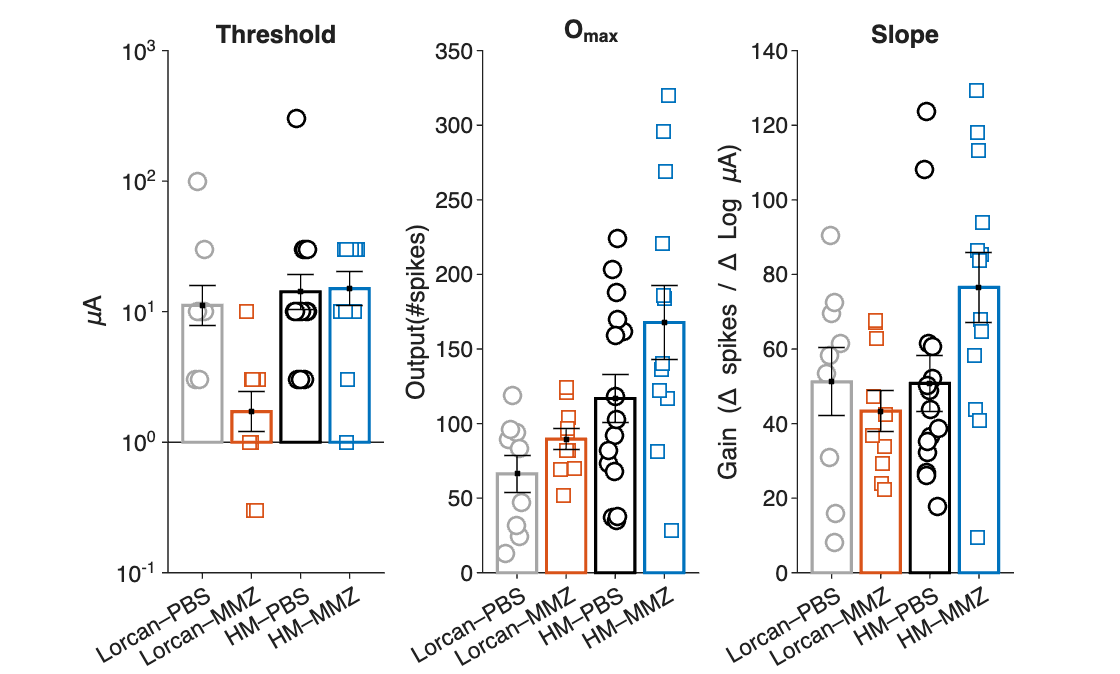


%% ---- Bar + points for threshold / Rmax / slope ----
figBars = figure('Color','w');
xJitter = 0.08;  ptSize = 40;

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    % x positions for the 4 groups
    xPos = 1:4;
    mu = nan(1,4); se = nan(1,4);

    for i = 1:numel(plotOrder)
        k = plotOrder{i};
        if ~isfield(stats,k), continue; end
        sty = styleMap.(k);

        % raw datapoints for this group & parameter
        parts = split(k,'_');  % {"HM","PBS"} or {"Lorcan","MMZ"}
        rows  = (T.Expter_Name==parts(1)) & (T.treatment==parts(2));
        yraw  = T{rows, varsParams(p)};

        if varsParams(p) == "threshold"
            ydp = log10(yraw);
            ydp(~isfinite(ydp)) = NaN;          % guard: remove <=0 or bad
            mu(i) = mean(ydp,'omitnan');
            se(i) = std(ydp,0,'omitnan') / sqrt(sum(~isnan(ydp)));

            scatter(xPos(i)+xJitter*randn(numel(ydp),1), ydp, ptSize, ...
                'Marker',sty.M,'MarkerEdgeColor',sty.C,'MarkerFaceColor','w','LineWidth',1);
        else
            mu(i) = stats.(k).meanPars(p);
            se(i) = stats.(k).semPars(p);

            scatter(xPos(i)+xJitter*randn(numel(yraw),1), yraw, ptSize, ...
                'Marker',sty.M,'MarkerEdgeColor',sty.C,'MarkerFaceColor','w','LineWidth',1);
        end

        % bars
        bar(xPos(i), mu(i), 'FaceColor','none', 'EdgeColor', sty.C, 'LineWidth',1.2);
    end

    % error bars
    ok = ismember(plotOrder, fieldnames(stats));
    errorbar(xPos(ok), mu(ok), se(ok), 'k.', 'CapSize',10);

    xlim([0.3 4.7]); xticks(xPos);
    xticklabels({'Lorcan–PBS','Lorcan–MMZ','HM–PBS','HM–MMZ'});
    set(gca,'TickDir','out');

    % (2–4) axis titles & special y formatting
    if varsParams(p) == "threshold"
        title('Threshold');
        ylim([-1 3]); yticks(-1:3);                                 % 10^-1 to 10^3
        yticklabels( arrayfun(@(k) sprintf('10^{%d}',k), -1:3, 'UniformOutput', false) );
        ylabel('\muA');
    elseif varsParams(p) == "Rmax"
        title('O_m_a_x');  % your original label scheme
        ylabel('Output(#spikes)');
    elseif varsParams(p) == "linear_interpolation_Slope"
        title('Slope');
        ylabel('Gain (\Delta spikes / \Delta Log \muA)');
    end
end

% save bar figure
exportgraphics(figBars, fullfile(outDir,'ParamsBars_threshold_Rmax_Slope.png'), 'Resolution',300);

### Compare by wpi & treatment

%% Compare by WPI (2w, 4w) & treatment (PBS, MMZ) for HM under aCSF
outDir = "/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/FigureOutputDirectory/PBS_MMZ_2w_4w_aCSF_HM_FigureOutputDir";
if ~exist(outDir,'dir'), mkdir(outDir); end

fname = "/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/summaryTbl/SummaryTable_PBS_MMZ_2w_4w_aCSF_HM_combined.xlsx";
T = readtable(fname, 'FileType','spreadsheet');

% --- columns we need
needCols = {'Expter_Name','wpi','Expt_cond','treatment','CellID','avgRundown_per_iteration'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

%% ---- FIXED FILTERS ----
expFilter  = "HM";     % experimenter
condFilter = "aCSF";   % condition

% keep only HM, aCSF, 2w/4w, PBS/MMZ
maskBase = strcmpi(T.Expter_Name,expFilter) & strcmpi(T.Expt_cond,condFilter) & ...
          (strcmpi(T.wpi,"2w") | strcmpi(T.wpi,"4w")) & ...
          (strcmpi(T.treatment,"PBS") | strcmpi(T.treatment,"MMZ"));

% ensure avgRundown_per_iteration is numeric and present
tmp = T.avgRundown_per_iteration;
if isnumeric(tmp)
    tmpd = double(tmp);
elseif iscell(tmp)
    tmpd = cellfun(@(y) str2double(string(y)), tmp);
else
    tmpd = str2double(string(tmp));
end
T.avgRundown_per_iteration = tmpd;

% (1) keep only rows that HAVE data in avgRundown_per_iteration
maskRundown = isfinite(T.avgRundown_per_iteration);
T = T(maskBase & maskRundown, :);

% sanity: repeated CellID within this subset?
ids = string(T.CellID);
[u,~,ic] = unique(ids,'stable');
counts = accumarray(ic,1);
dups = u(counts>1);
if ~isempty(dups)
    error('repeated cell: %s', strjoin(cellstr(dups), ', '));
end

%% ---- numeric columns ----
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","linear_interpolation_Slope"];
varsAll    = [varsSpikes varsParams];

for v = varsAll
    x = T.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end
    T.(v) = reshape(x,[],1);
end
T.treatment = string(T.treatment);
T.wpi       = string(T.wpi);

%% ---- build groups: WPI x treatment (within HM) ----
wpis      = ["2w","4w"];
treatList = ["PBS","MMZ"];

% COLORS / STYLES (2w filled, 4w open)
col.black  = [0 0 0];
col.blue   = [0 0.62 1.0];
col.purple = [0.45 0.20 0.70];
getColor = @(w,tr) ...
    (tr=="PBS"  & w=="2w") .* col.black  + ...
    (tr=="PBS"  & w=="4w") .* col.black  + ...
    (tr=="MMZ"  & w=="2w") .* col.blue   + ...
    (tr=="MMZ"  & w=="4w") .* col.purple;
getFace  = @(w,tr,C) (w=="2w") .* C + (w=="4w") .* [1 1 1];

% compute stats for each group
stats = struct();
for w = wpis
    for tr = treatList
        rows = (T.wpi==w) & (T.treatment==tr);
        if ~any(rows), continue; end

        Xspk = T{rows, varsSpikes};
        mSpk = mean(Xspk, 1, 'omitnan');
        sdSpk = std(Xspk, 0, 1, 'omitnan');
        nSpk = sum(~isnan(Xspk), 1);
        semSpk = sdSpk ./ max(nSpk,1).^0.5;

        Xpar = T{rows, varsParams};
        mPar = mean(Xpar, 1, 'omitnan');
        sdPar = std(Xpar, 0, 1, 'omitnan');
        nPar  = sum(~isnan(Xpar), 1);
        semPar = sdPar ./ max(nPar,1).^0.5;

        key = sprintf('a%s_%s', w, tr);   % e.g., "a2w_PBS"
        stats.(key).meanSpikes = mSpk;
        stats.(key).sdSpikes   = sdSpk;
        stats.(key).semSpikes  = semSpk;
        stats.(key).nSpikes    = nSpk;
        stats.(key).meanPars   = mPar;
        stats.(key).sdPars     = sdPar;
        stats.(key).semPars    = semPar;
        stats.(key).nPars      = nPar;
    end
end

%% ---- (5) Cell count per group (wpi x treatment), show & save
[groupID, groupTbl] = findgroups(T(:, {'wpi','treatment'}));
counts = splitapply(@numel, T.CellID, groupID);
CellCountTbl = groupTbl;
CellCountTbl.CellCount  = counts;
CellCountTbl.Percentage = 100*counts/sum(counts);
disp(CellCountTbl);

    wpi     treatment    CellCount    Percentage
    ____    _________    _________    __________

    "2w"      "MMZ"         13          19.697  
    "2w"      "PBS"         15          22.727  
    "4w"      "MMZ"         16          24.242  
    "4w"      "PBS"         22          33.333  



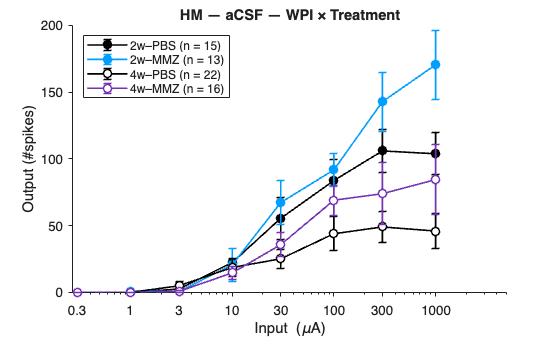

writetable(CellCountTbl, fullfile(outDir,'CellCounts_by_WPI_Treatment.csv'));

%% ---- IO curves (mean ± SEM) ----
xVals = [0.3 1 3 10 30 100 300 1000];   % µA
figIO = figure('Color','w'); hold on;

plotOrder = {'a2w_PBS','a2w_MMZ','a4w_PBS','a4w_MMZ'};
legNames  = {'2w–PBS (n = 15)','2w–MMZ (n = 13)','4w–PBS (n = 22)','4w–MMZ (n = 16)'};

for i = 1:numel(plotOrder)
    k = plotOrder{i}; if ~isfield(stats,k), continue; end
    parts = split(k,'_');  w = erase(parts(1),"a");  tr = parts(2);
    C = getColor(w,tr);
    mFace = getFace(w,tr,C);
    errorbar(xVals, stats.(k).meanSpikes, stats.(k).semSpikes, ...
        'o-','Color',C,'MarkerEdgeColor',C,'MarkerFaceColor',mFace, ...
        'LineWidth',1.2,'CapSize',6);
end

set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input (\muA)'); ylabel('Output (#spikes)');
legend(legNames( ismember(plotOrder, fieldnames(stats)) ), 'Location','northwest');
title(sprintf('%s — %s — WPI × Treatment', expFilter, condFilter));

exportgraphics(figIO, fullfile(outDir,'IOcurve_meanSEM.png'), 'Resolution',300);

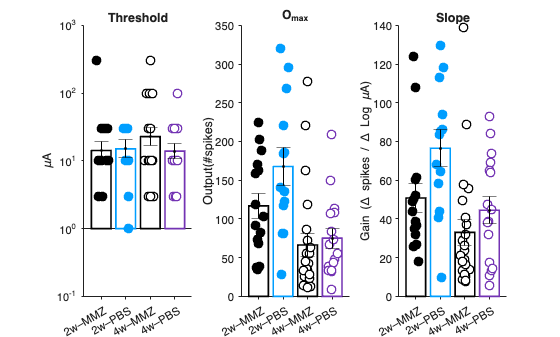


%% ---- Bar + points for threshold / Rmax / slope ----
figBars = figure('Color','w');
xJitter = 0.08;  ptSize = 40;

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    % order & x positions
    plotOrder = {'a2w_PBS','a2w_MMZ','a4w_PBS','a4w_MMZ',};
    xPos = 1:4;  mu = nan(1,4); se = nan(1,4);

    for i = 1:numel(plotOrder)
        k = plotOrder{i};
        if ~isfield(stats,k), continue; end
        parts = split(k,'_');  w = erase(parts(1),"a");  tr = parts(2);

        C     = getColor(w,tr);
        mFace = getFace(w,tr,C);

        % raw datapoints for this group & parameter
        rows = (T.wpi==w) & (T.treatment==tr);
        yraw = T{rows, varsParams(p)};

        if varsParams(p) == "threshold"
            % (2) transform per cell in log10 space
            ydp = log10(yraw);
            ydp(~isfinite(ydp)) = NaN;   % guard bad/<=0 values
            mu(i) = mean(ydp,'omitnan');
            se(i) = std(ydp,0,'omitnan') / sqrt(sum(~isnan(ydp)));

            scatter(xPos(i)+xJitter*randn(numel(ydp),1), ydp, ptSize, ...
                'Marker','o','MarkerEdgeColor',C,'MarkerFaceColor',mFace,'LineWidth',1);
        else
            mu(i) = stats.(k).meanPars(p);
            se(i) = stats.(k).semPars(p);

            scatter(xPos(i)+xJitter*randn(numel(yraw),1), yraw, ptSize, ...
                'Marker','o','MarkerEdgeColor',C,'MarkerFaceColor',mFace,'LineWidth',1);
        end

        % bars (edge only)
        bar(xPos(i), mu(i), 'FaceColor','none','EdgeColor',C,'LineWidth',1.2);
    end

    % error bars
    ok = ~isnan(mu);
    errorbar(xPos(ok), mu(ok), se(ok), 'k.', 'CapSize',10);

    xlim([0.3 4.7]); xticks(xPos);
    xticklabels({'2w–MMZ','2w–PBS','4w–MMZ','4w–PBS'});
    set(gca,'TickDir','out');

    % (2–4) titles & y-labels
    if varsParams(p) == "threshold"
        title('Threshold');
        ylim([-1 3]); yticks(-1:3);  % 10^-1 to 10^3 in log10 space
        yticklabels( arrayfun(@(k) sprintf('10^{%d}',k), -1:3, 'UniformOutput', false) );
        ylabel('\muA');
    elseif varsParams(p) == "Rmax"
        title('O_m_a_x');
        ylabel('Output(#spikes)');
    elseif varsParams(p) == "linear_interpolation_Slope"
        title('Slope');
        ylabel('Gain (\Delta spikes / \Delta Log \muA)');
    end
end

exportgraphics(figBars, fullfile(outDir,'ParamsBars_threshold_Rmax_Slope.png'), 'Resolution',300);

### Compare by experimental conditions

#### PBS

% === Compare bath condition (aCSF vs GBZ) for a chosen experimenter & treatment at 2w ===

% --- Figure Output directory ---
outDir = "/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/FigureOutputDirectory/PBS_2w_aCSF-GBZ_HM_FigureOutputDir";
if ~exist(outDir,'dir'), mkdir(outDir); end

% --- Excel file input directory ---
fname = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/summaryTbl/SummaryTable_PBS_MMZ_2w_aCSF-GBZ_HM_all.xlsx';
T = readtable(fname, 'FileType','spreadsheet');

% --- required columns
needCols = {'Expter_Name','wpi','treatment','Expt_cond','CellID','avgRundown_per_iteration'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

%% ---- QUICK FILTERS ----
expFilter     = "HM";      % who ran it
wpiFilter     = "2w";
treatFilter   = "PBS";     % change to "MMZ" to compare HM_2w_MMZ_aCSF vs HM_2w_MMZ_GBZ
condsToCompare = ["aCSF","GBZ","NBQX_APV"];  % we are pairing only these two

% --- convert avgRundown_per_iteration to numeric and require data
tmp = T.avgRundown_per_iteration;
if isnumeric(tmp)
    tmpd = double(tmp);
elseif iscell(tmp)
    tmpd = cellfun(@(y) str2double(string(y)), tmp);
else
    tmpd = str2double(string(tmp));
end
T.avgRundown_per_iteration = tmpd;
hasRun = isfinite(T.avgRundown_per_iteration);   % add & tmpd~=0 if you also want to drop zeros

% base mask: HM @ 2w, chosen treatment, and condition is aCSF or GBZ
mask = strcmpi(T.Expter_Name,expFilter) & ...
       strcmpi(T.wpi,wpiFilter) & ...
       strcmpi(T.treatment,treatFilter) & ...
       (strcmpi(T.Expt_cond,"aCSF") | strcmpi(T.Expt_cond,"GBZ")| strcmpi(T.Expt_cond,"NBQX_APV")) & ...
       hasRun;

T = T(mask,:);

%% ===== NEW: keep only CellIDs that have BOTH aCSF & GBZ =====
ids   = string(T.CellID);
conds = string(T.Expt_cond);

ids_a = unique(ids(strcmpi(conds,'aCSF')));
ids_g = unique(ids(strcmpi(conds,'GBZ')));

ids_keep = intersect(ids_a, ids_g);        % CellIDs present in BOTH conditions
T = T(ismember(ids, ids_keep), :);

% (optional) warn if anything got dropped by pairing
% fprintf('Paired CellIDs kept: %d (from %d total after base filter)\n', numel(ids_keep), numel(unique(ids)));

%% ---- numeric columns ----
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","linear_interpolation_Slope"];
for v = [varsSpikes varsParams]
    x = T.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end
    T.(v) = reshape(x,[],1);
end
T.Expt_cond = string(T.Expt_cond);

%% ---- COLORS & HELPERS (auto-switch by treatFilter) ----
if treatFilter=="PBS"
    pal.ctrl = [0 0 0];            % aCSF under PBS
    pal.drug = [0.18 0.80 0.60];   % +GBZ under PBS (mint)
    pal.nbqx = 0.45*[1 1 1];       % +NBQX/APV under PBS (gray)
elseif treatFilter=="MMZ"
    pal.ctrl = [0 0.62 1.00];      % aCSF under MMZ (blue)
    pal.drug = [0.98 0.60 0.20];   % +GBZ under MMZ (orange)
    pal.nbqx = 0.45*[1 1 1];    % +NBQX/APV under MMZ (gray)
else
    % fallback (shouldn't happen)
    pal.ctrl = [0 0 0];
    pal.drug = [0.5 0.5 0.5];
    pal.nbqx = [0.3 0.3 0.8];
end

% color/face by condition only (treatFilter already encoded in palette)
getColor = @(cond) ...
    (cond=="aCSF")    * pal.ctrl + ...
    (cond=="GBZ")     * pal.drug + ...
    (cond=="NBQX_APV")* pal.nbqx;

% aCSF filled, drugs open
getFace  = @(cond,C) (cond=="aCSF").*C + (cond~="aCSF").*[1 1 1];

%% ---- compute stats per condition ----
order = cellstr(condsToCompare);
stats = struct();
for i = 1:numel(order)
    c = string(order{i});
    rows = (T.Expt_cond==c);
    if ~any(rows), continue; end

    Xspk = T{rows, varsSpikes};
    Xpar = T{rows, varsParams};

    mSpk = mean(Xspk,1,'omitnan');
    sdSpk = std(Xspk,0,1,'omitnan');
    nSpk  = sum(~isnan(Xspk),1);
    semSpk = sdSpk ./ sqrt(max(nSpk,1));

    mPar = mean(Xpar,1,'omitnan');
    sdPar = std(Xpar,0,1,'omitnan');
    nPar  = sum(~isnan(Xpar),1);
    semPar = sdPar ./ sqrt(max(nPar,1));

    key = char(c);
    stats.(key).meanSpikes = mSpk;
    stats.(key).semSpikes  = semSpk;
    stats.(key).meanPars   = mPar;
    stats.(key).semPars    = semPar;
end

%% ---- Cell count per condition (after pairing), show & save
[groupID, groupTbl] = findgroups(T(:, {'Expt_cond'}));
counts = splitapply(@numel, T.CellID, groupID);
CellCountTbl = groupTbl;
CellCountTbl.CellCount  = counts;
CellCountTbl.Percentage = 100*counts/sum(counts);
disp(CellCountTbl);

    Expt_cond     CellCount    Percentage
    __________    _________    __________

    "GBZ"             7          43.75   
    "NBQX_APV"        2           12.5   
    "aCSF"            7          43.75   



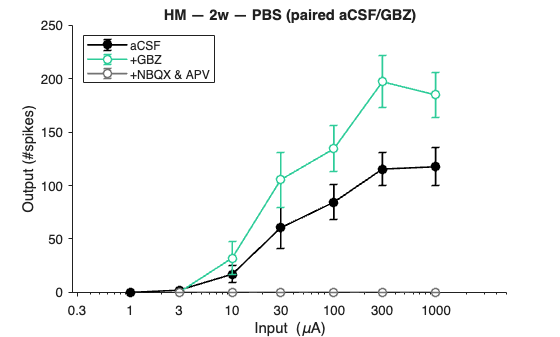

writetable(CellCountTbl, fullfile(outDir,'CellCounts_by_Condition_paired.csv'));

%% ---- IO curves ----
xVals = [0.3 1 3 10 30 100 300 1000];
figIO = figure('Color','w'); hold on;

legTxt = ["aCSF","GBZ","+NBQX & APV"];
legTxt(strcmpi(order,'GBZ'))  = {'+GBZ'};

for i = 1:numel(order)
    k = order{i}; if ~isfield(stats,k), continue; end
    C    = getColor(string(k));
    Face = getFace (string(k), C);

    errorbar(xVals, stats.(k).meanSpikes, stats.(k).semSpikes, ...
        'o-','Color',C,'MarkerEdgeColor',C,'MarkerFaceColor',Face, ...
        'LineWidth',1.2,'CapSize',6);
end
set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input (\muA)'); ylabel('Output (#spikes)');
title(sprintf('%s — %s — %s (paired aCSF/GBZ)', expFilter, wpiFilter, treatFilter));
legend(legTxt,'Location','northwest');

exportgraphics(figIO, fullfile(outDir,'IOcurve_meanSEM_paired.png'), 'Resolution',300);

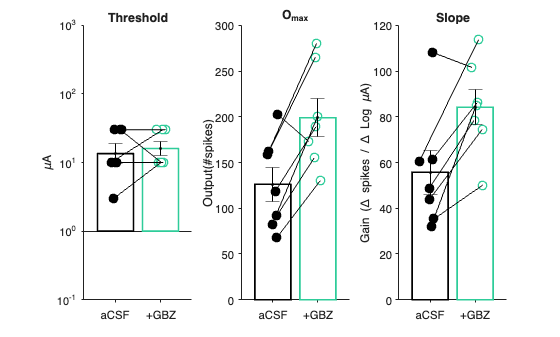

%% ---- Bar + points for threshold / Rmax / slope (with CellID-connecting lines) ----
figBars = figure('Color','w'); xJitter = 0.08; ptSize = 40;

% We only plot aCSF vs GBZ in bars
new_order  = cellstr(["aCSF","GBZ"]);
new_legTxt = {'aCSF','+GBZ'};

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    mu = nan(1,numel(new_order)); se = nan(1,numel(new_order));

    % Keep jittered coords + IDs for connecting same-CellID pairs
    scat = struct();  % scat.<cond>: .id, .x, .y

    for i = 1:numel(new_order)
        k = new_order{i}; if ~isfield(stats,k), continue; end
        rows = (T.Expt_cond==string(k));
        C    = getColor(string(k));
        Face = getFace (string(k), C);

        % y values in the correct space
        if varsParams(p) == "threshold"
            y = log10(T{rows,'threshold'});     % log10 per-cell
            y(~isfinite(y)) = NaN;
        else
            y = T{rows, varsParams(p)};
        end

        % summary stats
        mu(i) = mean(y,'omitnan');
        se(i) = std(y,0,'omitnan') / sqrt(sum(~isnan(y)));

        % jittered x (reused for the connecting lines)
        xj = i + xJitter*randn(numel(y),1);

        % dots
        scatter(xj, y, ptSize, 'o', ...
            'MarkerEdgeColor',C,'MarkerFaceColor',Face,'LineWidth',1);

        % bar
        b = bar(i, mu(i)); b.FaceColor = 'none'; b.EdgeColor = C; b.LineWidth = 1.2;

        % stash for pairing
        scat.(k).id = string(T.CellID(rows));
        scat.(k).x  = xj;
        scat.(k).y  = y;
    end

    % error bars
    good = ~isnan(mu);
    errorbar(find(good), mu(good), se(good), 'k.', 'CapSize',10);

    % ---- connect same-CellID between aCSF and GBZ ----
    if isfield(scat,'aCSF') && isfield(scat,'GBZ')
        [common, ia, ib] = intersect(scat.aCSF.id, scat.GBZ.id, 'stable');
        for t = 1:numel(common)
            plot([scat.aCSF.x(ia(t)) scat.GBZ.x(ib(t))], ...
                 [scat.aCSF.y(ia(t)) scat.GBZ.y(ib(t))], ...
                 'k-','LineWidth',0.1);
        end
    end

    % axes & labels
    xlim([0.3 numel(new_order)+0.7]); xticks(1:numel(new_order)); xticklabels(new_legTxt);
    set(gca,'TickDir','out');

    switch varsParams(p)
        case "threshold"
            title('Threshold');
            ylim([-1 3]); yticks(-1:3);
            yticklabels(arrayfun(@(k) sprintf('10^{%d}',k), -1:3, 'UniformOutput', false));
            ylabel('\muA');
        case "Rmax"
            title('O_m_a_x');
            ylabel('Output(#spikes)');
        case "linear_interpolation_Slope"
            title('Slope');
            ylabel('Gain (\Delta spikes / \Delta Log \muA)');
    end
end

exportgraphics(figBars, fullfile(outDir,'ParamsBars_threshold_Rmax_Slope_paired.png'), 'Resolution',300);

#### MMZ

% === Compare bath condition (aCSF vs GBZ) for a chosen experimenter & treatment at 2w ===

% --- Figure Output directory ---
outDir = "/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/FigureOutputDirectory/MMZ_2w_aCSF-GBZ_HM_FigureOutputDir";
if ~exist(outDir,'dir'), mkdir(outDir); end

% --- Excel file input directory ---
fname = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/summaryTbl/SummaryTable_PBS_MMZ_2w_aCSF-GBZ_HM_all.xlsx';
T = readtable(fname, 'FileType','spreadsheet');

% --- required columns
needCols = {'Expter_Name','wpi','treatment','Expt_cond','CellID','avgRundown_per_iteration'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

%% ---- QUICK FILTERS ----
expFilter     = "HM";      % who ran it
wpiFilter     = "2w";
treatFilter   = "MMZ";     % change to "MMZ" to compare HM_2w_MMZ_aCSF vs HM_2w_MMZ_GBZ
condsToCompare = ["aCSF","GBZ","NBQX_APV"];  % we are pairing only these two

% --- convert avgRundown_per_iteration to numeric and require data
tmp = T.avgRundown_per_iteration;
if isnumeric(tmp)
    tmpd = double(tmp);
elseif iscell(tmp)
    tmpd = cellfun(@(y) str2double(string(y)), tmp);
else
    tmpd = str2double(string(tmp));
end
T.avgRundown_per_iteration = tmpd;
hasRun = isfinite(T.avgRundown_per_iteration);   % add & tmpd~=0 if you also want to drop zeros

% base mask: HM @ 2w, chosen treatment, and condition is aCSF or GBZ
mask = strcmpi(T.Expter_Name,expFilter) & ...
       strcmpi(T.wpi,wpiFilter) & ...
       strcmpi(T.treatment,treatFilter) & ...
       (strcmpi(T.Expt_cond,"aCSF") | strcmpi(T.Expt_cond,"GBZ")| strcmpi(T.Expt_cond,"NBQX_APV")) & ...
       hasRun;

T = T(mask,:);

%% ===== NEW: keep only CellIDs that have BOTH aCSF & GBZ =====
ids   = string(T.CellID);
conds = string(T.Expt_cond);

ids_a = unique(ids(strcmpi(conds,'aCSF')));
ids_g = unique(ids(strcmpi(conds,'GBZ')));

ids_keep = intersect(ids_a, ids_g);        % CellIDs present in BOTH conditions
T = T(ismember(ids, ids_keep), :);

% (optional) warn if anything got dropped by pairing
% fprintf('Paired CellIDs kept: %d (from %d total after base filter)\n', numel(ids_keep), numel(unique(ids)));

%% ---- numeric columns ----
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","linear_interpolation_Slope"];
for v = [varsSpikes varsParams]
    x = T.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end
    T.(v) = reshape(x,[],1);
end
T.Expt_cond = string(T.Expt_cond);

%% ---- COLORS & HELPERS (auto-switch by treatFilter) ----
if treatFilter=="PBS"
    pal.ctrl = [0 0 0];            % aCSF under PBS
    pal.drug = [0.18 0.80 0.60];   % +GBZ under PBS (mint)
    pal.nbqx = 0.45*[1 1 1];       % +NBQX/APV under PBS (gray)
elseif treatFilter=="MMZ"
    pal.ctrl = [0 0.62 1.00];      % aCSF under MMZ (blue)
    pal.drug = [0.98 0.60 0.20];   % +GBZ under MMZ (orange)
    pal.nbqx = 0.45*[1 1 1];    % +NBQX/APV under MMZ (gray)
else
    % fallback (shouldn't happen)
    pal.ctrl = [0 0 0];
    pal.drug = [0.5 0.5 0.5];
    pal.nbqx = [0.3 0.3 0.8];
end

% color/face by condition only (treatFilter already encoded in palette)
getColor = @(cond) ...
    (cond=="aCSF")    * pal.ctrl + ...
    (cond=="GBZ")     * pal.drug + ...
    (cond=="NBQX_APV")* pal.nbqx;

% aCSF filled, drugs open
getFace  = @(cond,C) (cond=="aCSF").*C + (cond~="aCSF").*[1 1 1];

%% ---- compute stats per condition ----
order = cellstr(condsToCompare);
stats = struct();
for i = 1:numel(order)
    c = string(order{i});
    rows = (T.Expt_cond==c);
    if ~any(rows), continue; end

    Xspk = T{rows, varsSpikes};
    Xpar = T{rows, varsParams};

    mSpk = mean(Xspk,1,'omitnan');
    sdSpk = std(Xspk,0,1,'omitnan');
    nSpk  = sum(~isnan(Xspk),1);
    semSpk = sdSpk ./ sqrt(max(nSpk,1));

    mPar = mean(Xpar,1,'omitnan');
    sdPar = std(Xpar,0,1,'omitnan');
    nPar  = sum(~isnan(Xpar),1);
    semPar = sdPar ./ sqrt(max(nPar,1));

    key = char(c);
    stats.(key).meanSpikes = mSpk;
    stats.(key).semSpikes  = semSpk;
    stats.(key).meanPars   = mPar;
    stats.(key).semPars    = semPar;
end

%% ---- Cell count per condition (after pairing), show & save
[groupID, groupTbl] = findgroups(T(:, {'Expt_cond'}));
counts = splitapply(@numel, T.CellID, groupID);
CellCountTbl = groupTbl;
CellCountTbl.CellCount  = counts;
CellCountTbl.Percentage = 100*counts/sum(counts);
disp(CellCountTbl);

    Expt_cond     CellCount    Percentage
    __________    _________    __________

    "GBZ"             7          46.667  
    "NBQX_APV"        1          6.6667  
    "aCSF"            7          46.667  



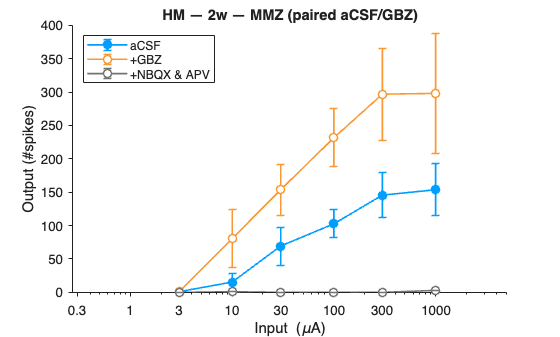

writetable(CellCountTbl, fullfile(outDir,'CellCounts_by_Condition_paired.csv'));

%% ---- IO curves ----
xVals = [0.3 1 3 10 30 100 300 1000];
figIO = figure('Color','w'); hold on;

legTxt = ["aCSF","GBZ","+NBQX & APV"];
legTxt(strcmpi(order,'GBZ'))  = {'+GBZ'};

for i = 1:numel(order)
    k = order{i}; if ~isfield(stats,k), continue; end
    C    = getColor(string(k));
    Face = getFace (string(k), C);

    errorbar(xVals, stats.(k).meanSpikes, stats.(k).semSpikes, ...
        'o-','Color',C,'MarkerEdgeColor',C,'MarkerFaceColor',Face, ...
        'LineWidth',1.2,'CapSize',6);
end
set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input (\muA)'); ylabel('Output (#spikes)');
title(sprintf('%s — %s — %s (paired aCSF/GBZ)', expFilter, wpiFilter, treatFilter));
legend(legTxt,'Location','northwest');

exportgraphics(figIO, fullfile(outDir,'IOcurve_meanSEM_paired.png'), 'Resolution',300);

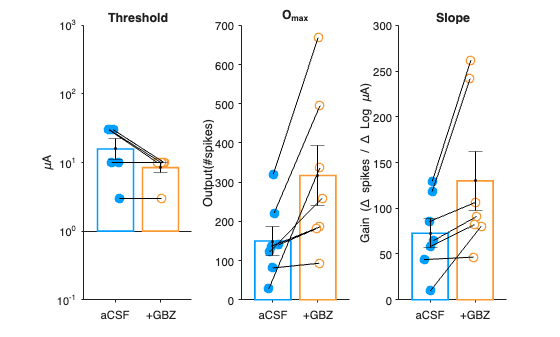

%% ---- Bar + points for threshold / Rmax / slope (with CellID-connecting lines) ----
figBars = figure('Color','w'); xJitter = 0.08; ptSize = 40;

% We only plot aCSF vs GBZ in bars
new_order  = cellstr(["aCSF","GBZ"]);
new_legTxt = {'aCSF','+GBZ'};

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    mu = nan(1,numel(new_order)); se = nan(1,numel(new_order));

    % Keep jittered coords + IDs for connecting same-CellID pairs
    scat = struct();  % scat.<cond>: .id, .x, .y

    for i = 1:numel(new_order)
        k = new_order{i}; if ~isfield(stats,k), continue; end
        rows = (T.Expt_cond==string(k));
        C    = getColor(string(k));
        Face = getFace (string(k), C);

        % y values in the correct space
        if varsParams(p) == "threshold"
            y = log10(T{rows,'threshold'});     % log10 per-cell
            y(~isfinite(y)) = NaN;
        else
            y = T{rows, varsParams(p)};
        end

        % summary stats
        mu(i) = mean(y,'omitnan');
        se(i) = std(y,0,'omitnan') / sqrt(sum(~isnan(y)));

        % jittered x (reused for the connecting lines)
        xj = i + xJitter*randn(numel(y),1);

        % dots
        scatter(xj, y, ptSize, 'o', ...
            'MarkerEdgeColor',C,'MarkerFaceColor',Face,'LineWidth',1);

        % bar
        b = bar(i, mu(i)); b.FaceColor = 'none'; b.EdgeColor = C; b.LineWidth = 1.2;

        % stash for pairing
        scat.(k).id = string(T.CellID(rows));
        scat.(k).x  = xj;
        scat.(k).y  = y;
    end

    % error bars
    good = ~isnan(mu);
    errorbar(find(good), mu(good), se(good), 'k.', 'CapSize',10);

    % ---- connect same-CellID between aCSF and GBZ ----
    if isfield(scat,'aCSF') && isfield(scat,'GBZ')
        [common, ia, ib] = intersect(scat.aCSF.id, scat.GBZ.id, 'stable');
        for t = 1:numel(common)
            plot([scat.aCSF.x(ia(t)) scat.GBZ.x(ib(t))], ...
                 [scat.aCSF.y(ia(t)) scat.GBZ.y(ib(t))], ...
                 'k-','LineWidth',0.1);
        end
    end

    % axes & labels
    xlim([0.3 numel(new_order)+0.7]); xticks(1:numel(new_order)); xticklabels(new_legTxt);
    set(gca,'TickDir','out');

    switch varsParams(p)
        case "threshold"
            title('Threshold');
            ylim([-1 3]); yticks(-1:3);
            yticklabels(arrayfun(@(k) sprintf('10^{%d}',k), -1:3, 'UniformOutput', false));
            ylabel('\muA');
        case "Rmax"
            title('O_m_a_x');
            ylabel('Output(#spikes)');
        case "linear_interpolation_Slope"
            title('Slope');
            ylabel('Gain (\Delta spikes / \Delta Log \muA)');
    end
end

exportgraphics(figBars, fullfile(outDir,'ParamsBars_threshold_Rmax_Slope_paired.png'), 'Resolution',300);

### Compare by experimental condition & Treatment

%% Compare aCSF vs +GBZ for PBS & MMZ at 2w (HM only) — paired CellIDs only
outDir = "/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/FigureOutputDirectory/PBS_MMZ_2w_aCSF-GBZ_HM_Combined_FigureOutputDir";
if ~exist(outDir,'dir'), mkdir(outDir); end

% ====== DATA ======
fname = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/summaryTbl/SummaryTable_PBS_MMZ_2w_aCSF-GBZ_HM_all.xlsx';   % <- put your spreadsheet here
T = readtable(fname, 'FileType','spreadsheet');

% Required columns to normalize to string
needCols = {'Expter_Name','wpi','treatment','Expt_cond','CellID','avgRundown_per_iteration'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

% Filters: HM, 2w, PBS/MMZ, aCSF/GBZ
mask = strcmpi(T.Expter_Name,"HM") & strcmpi(T.wpi,"2w") & ...
       (strcmpi(T.treatment,"PBS") | strcmpi(T.treatment,"MMZ")) & ...
       (strcmpi(T.Expt_cond,"aCSF") | strcmpi(T.Expt_cond,"GBZ"));
T = T(mask,:);

% Make numeric copies (needed for filtering & plotting)
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","linear_interpolation_Slope"];
varRundown = "avgRundown_per_iteration";
for v = [varsSpikes varRundown varsParams]
    x = T.(v); if ~isnumeric(x), x = str2double(string(x)); end
    T.(v) = reshape(double(x),[],1);
end
T.treatment = string(T.treatment);
T.Expt_cond = string(T.Expt_cond);

% ====== Keep only CellIDs that have BOTH aCSF & GBZ and HAVE rundown data in BOTH ======
[G, ~] = findgroups(T.CellID);
condsByCell = splitapply(@(c) {unique(string(c))}, T.Expt_cond, G);
hasBoth     = cellfun(@(u) all(ismember(["aCSF","GBZ"], u)), condsByCell);
rundownOK   = splitapply(@(x) all(isfinite(x)), T.(varRundown), G);
T = T( hasBoth(G) & rundownOK(G), : );

% ====== Cell counts per treatment x condition (after pairing) ======
try
    CellCountTbl = groupcounts(T, {'treatment','Expt_cond'});
    CellCountTbl.Properties.VariableNames = {'treatment','Expt_cond','CellCount','Percentage'};
catch
    % fallback for older MATLAB
    [gid, keyTbl] = findgroups(T(:,{'treatment','Expt_cond'}));
    cnt = splitapply(@numel, T.CellID, gid);
    CellCountTbl = keyTbl; CellCountTbl.CellCount = cnt;
    CellCountTbl.Percentage = 100*cnt/sum(cnt);
end
disp(CellCountTbl);

    treatment    Expt_cond    CellCount    Percentage
    _________    _________    _________    __________

      "MMZ"       "GBZ"           7            25    
      "MMZ"       "aCSF"          7            25    
      "PBS"       "GBZ"           7            25    
      "PBS"       "aCSF"          7            25    



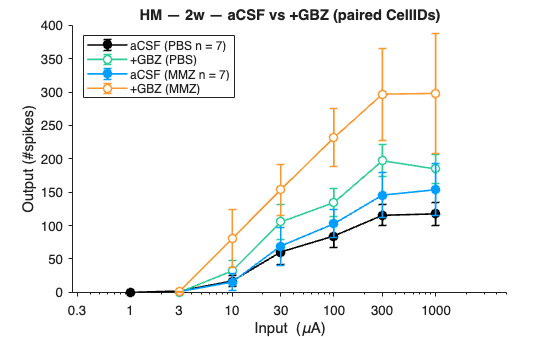

writetable(CellCountTbl, fullfile(outDir,'CellCounts_treatment_by_condition_paired.csv'));

% ====== Color/style map (PBS: black/mint; MMZ: blue/orange) ======
col.black  = [0 0 0];          % PBS aCSF
col.mint   = [0.18 0.80 0.60]; % PBS +GBZ
col.blue   = [0 0.62 1.00];    % MMZ aCSF
col.orange = [0.98 0.60 0.20]; % MMZ +GBZ

styleMap = struct( ...
  'PBS_aCSF', struct('C',col.black,  'Face',col.black ), ...
  'PBS_GBZ',  struct('C',col.mint,   'Face',[1 1 1]   ), ...
  'MMZ_aCSF', struct('C',col.blue,   'Face',col.blue  ), ...
  'MMZ_GBZ',  struct('C',col.orange, 'Face',[1 1 1]   ) ...
);

% ====== Stats per group ======
pairs = {'PBS_aCSF','PBS_GBZ','MMZ_aCSF','MMZ_GBZ'};   % canonical order
stats = struct();
for i = 1:numel(pairs)
    pc = split(pairs{i},'_');  tr = pc(1);  cond = pc(2);
    rows = (T.treatment==tr) & (T.Expt_cond==cond);
    if ~any(rows), continue; end

    Xspk = T{rows, varsSpikes};
    Xpar = T{rows, varsParams};

    mSpk = mean(Xspk,1,'omitnan');  sdSpk = std(Xspk,0,1,'omitnan');
    nSpk = sum(~isnan(Xspk),1);     semSpk = sdSpk./sqrt(max(nSpk,1));

    mPar = mean(Xpar,1,'omitnan');  sdPar = std(Xpar,0,1,'omitnan');
    nPar = sum(~isnan(Xpar),1);     semPar = sdPar./sqrt(max(nPar,1));

    stats.(pairs{i}).meanSpikes = mSpk;
    stats.(pairs{i}).semSpikes  = semSpk;
    stats.(pairs{i}).meanPars   = mPar;
    stats.(pairs{i}).semPars    = semPar;
end

% ====== IO curves (mean ± SEM) ======
xVals = [0.3 1 3 10 30 100 300 1000];
figIO = figure('Color','w'); hold on;

plotOrder = {'PBS_aCSF','PBS_GBZ','MMZ_aCSF','MMZ_GBZ'};
legNames  = {'aCSF (PBS n = 7)','+GBZ (PBS)','aCSF (MMZ n = 7)','+GBZ (MMZ)'};

for i = 1:numel(plotOrder)
    k = plotOrder{i}; if ~isfield(stats,k), continue; end
    st  = stats.(k); stl = styleMap.(k);
    errorbar(xVals, st.meanSpikes, st.semSpikes, ...
        'o-','Color',stl.C,'MarkerEdgeColor',stl.C,'MarkerFaceColor',stl.Face, ...
        'LineWidth',1.2,'CapSize',6);
end
set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input (\muA)'); ylabel('Output (#spikes)');
legend(legNames( ismember(plotOrder, fieldnames(stats)) ), 'Location','northwest');
title('HM — 2w — aCSF vs +GBZ (paired CellIDs)');

exportgraphics(figIO, fullfile(outDir,'IOcurve_meanSEM.png'), 'Resolution',300);

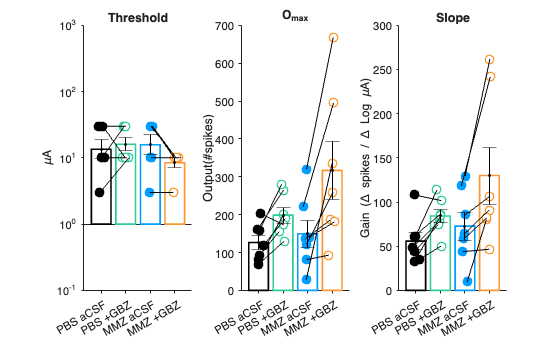


% ====== Bar + points for Threshold / Rmax / Slope (with pairing lines) ======
figBars = figure('Color','w'); xJitter = 0.08; ptSize = 40;

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    xPos = 1:numel(plotOrder);
    mu = nan(1,numel(plotOrder)); se = nan(1,numel(plotOrder));

    % store scatter coordinates by group to connect pairs later
    scat = struct();  % scat.(group).id, .x, .y

    for i = 1:numel(plotOrder)
        k = plotOrder{i}; if ~isfield(stats,k), continue; end
        stl = styleMap.(k);
        pc = split(k,'_');  tr = pc(1);  cond = pc(2);
        rows = (T.treatment==tr) & (T.Expt_cond==cond);

        % y values (log10 for threshold, raw otherwise)
        if varsParams(p)=="threshold"
            y = log10(T{rows,'threshold'});
            y(~isfinite(y)) = NaN;
        else
            y = T{rows, varsParams(p)};
        end

        % summary stats
        mu(i) = mean(y,'omitnan');
        se(i) = std(y,0,'omitnan') / sqrt(sum(~isnan(y)));

        % jittered x used for BOTH scatter and connecting lines
        j = xJitter*randn(numel(y),1);
        xScatter = xPos(i) + j;

        % plot points
        scatter(xScatter, y, ptSize, ...
            'Marker','o','MarkerEdgeColor',stl.C,'MarkerFaceColor',stl.Face,'LineWidth',1);

        % bar
        bar(xPos(i), mu(i), 'FaceColor','none','EdgeColor',stl.C,'LineWidth',1.2);

        % remember coordinates and IDs for pairing
        scat.(k).id = string(T.CellID(rows));
        scat.(k).x  = xScatter;
        scat.(k).y  = y;
    end

    % error bars
    good = ~isnan(mu);
    errorbar(xPos(good), mu(good), se(good), 'k.', 'CapSize',10);

    % ---- NEW: connect same-CellID pairs aCSF <-> GBZ within each treatment ----
    for tr = ["PBS","MMZ"]
        g1 = sprintf('%s_aCSF', tr);
        g2 = sprintf('%s_GBZ',  tr);
        if isfield(scat,g1) && isfield(scat,g2)
            [common, ia, ib] = intersect(scat.(g1).id, scat.(g2).id, 'stable');
            for t = 1:numel(common)
                plot([scat.(g1).x(ia(t)) scat.(g2).x(ib(t))], ...
                     [scat.(g1).y(ia(t)) scat.(g2).y(ib(t))], ...
                     'k-','LineWidth',0.1);   % black connecting line
            end
        end
    end

    % axes & labels
    xlim([0.3 numel(plotOrder)+0.7]); xticks(xPos);
    xticklabels({'PBS aCSF','PBS +GBZ','MMZ aCSF','MMZ +GBZ'});
    set(gca,'TickDir','out');

    switch varsParams(p)
        case "threshold"
            title('Threshold');
            ylim([-1 3]); yticks(-1:3);                               % 10^-1 to 10^3
            yticklabels(arrayfun(@(k) sprintf('10^{%d}',k), -1:3, 'UniformOutput',false));
            ylabel('\muA');
        case "Rmax"
            title('O_m_a_x');
            ylabel('Output(#spikes)');
        case "linear_interpolation_Slope"
            title('Slope');
            ylabel('Gain (\Delta spikes / \Delta Log \muA)');
    end
end

exportgraphics(figBars, fullfile(outDir,'ParamsBars_threshold_Rmax_Slope.png'), 'Resolution',300);